% Settings
clear;

## Background

### Cycles

T = 1;
[c1,t1] = elvio_resample(elvio_cycle_us_ftp75(),1);
[c2,t2] = elvio_resample(elvio_cycle_eu_nedc(),1);
[c3,t3] = elvio_resample(elvio_cycle_cadc_urm150(),1);
x = NaN(length(c3),3);
x(1:length(c1),1) = c1;
x(1:length(c2),2) = c2;
x(1:length(c3),3) = c3;

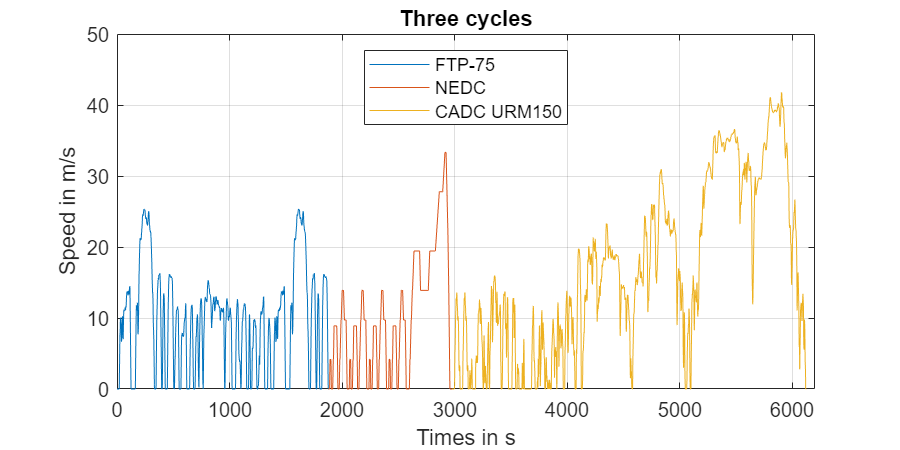

f=figure;
f.Position(3:4)=[600 300];
hold off;
plot(t1,c1);
hold on;
plot(t1(end)+t2,c2);
plot(t1(end)+t2(end)+t3,c3);
xlabel("Times in s");
ylabel('Speed in m/s');
title("Three cycles");
legend("FTP-75","NEDC","CADC URM150","Location","north");
xlim([0 6200]);
grid;
hold off;

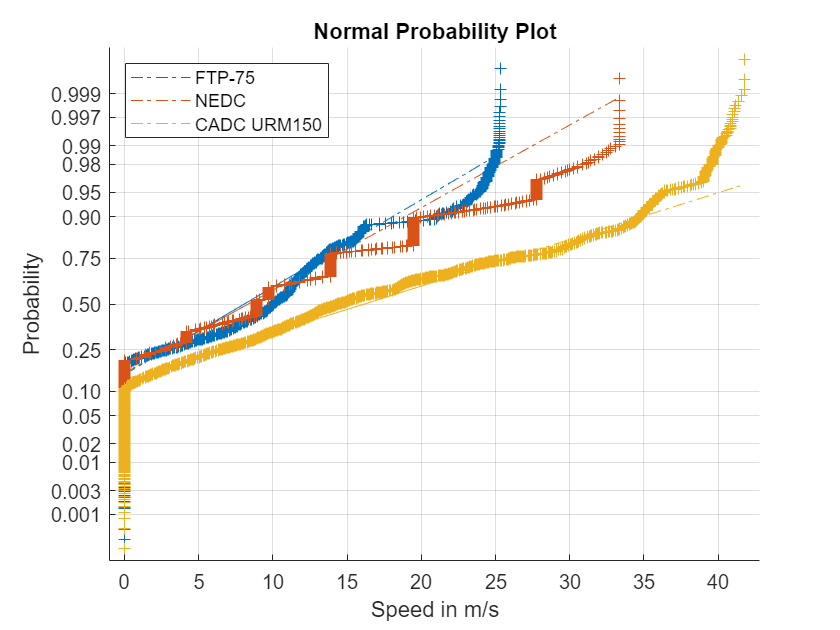

figure;
normplot(x);
legend("FTP-75","NEDC","CADC URM150","Location","northwest");
xlabel("Speed in m/s");

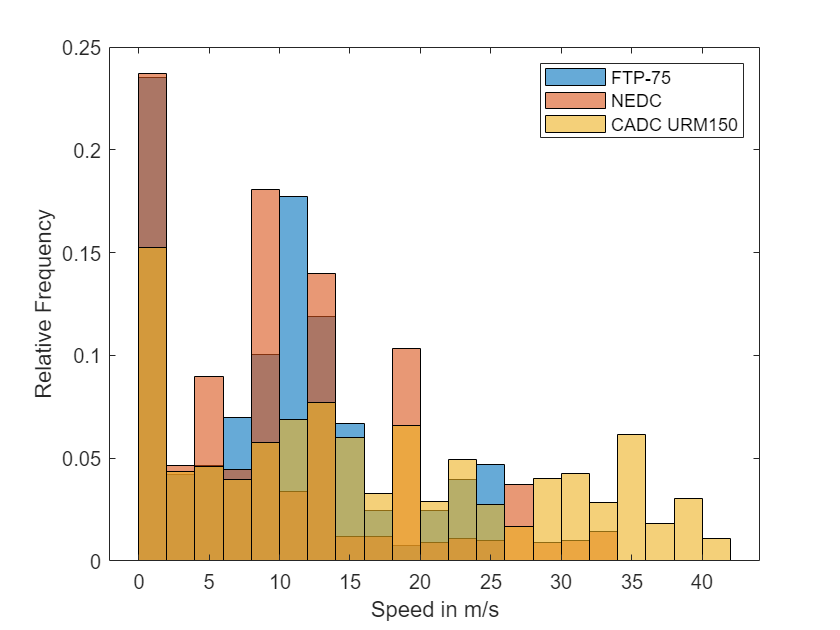

figure;
hold off
h = histogram(c1);
h.Normalization = 'probability';
h.BinWidth = 2;
hold on
h = histogram(c2);
h.Normalization = 'probability';
h.BinWidth = 2;
h = histogram(c3);
h.Normalization = 'probability';
h.BinWidth = 2;
hold off
legend("FTP-75","NEDC","CADC URM150");
xlabel("Speed in m/s");
ylabel("Relative Frequency");

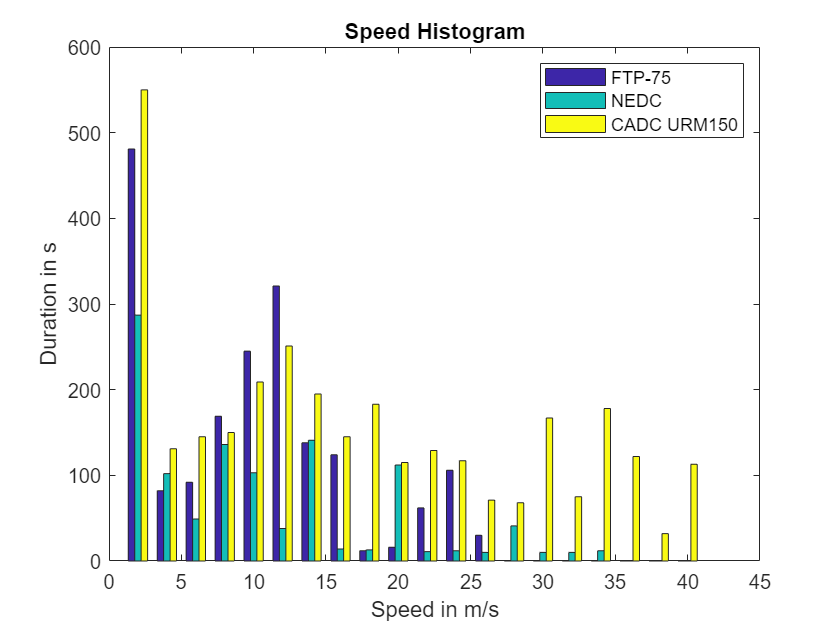

figure;
hist(x,2:2:40);
legend("FTP-75","NEDC","CADC URM150");
xlabel("Speed in m/s");
ylabel("Duration in s");
title("Speed Histogram");

cycles = ["us_ftp75","us_us06","eu_nedc","wltp_3b","cadc_urm150","cadc_urban","cadc_rural","cadc_mw150"];
d = table();
for Cycle = cycles
    c = eval("elvio_cycle_"+Cycle+"()");
    [v,t,a] = elvio_resample(c,0.1);
    Duration = t(end);

    Stopped = sum(v==0)/10;

    Mean_Speed = mean(v);
    sd = std(v);
    sk = skewness(v);
    kt = kurtosis(v);

    Abs_Acc = mean(abs(a));
    asq  = mean(a.^2);
    va   = mean(v.*v.*a.*a);
    PKE  = mean(v.*a.*(0.5+0.5*sign(a)));

    t1 = table(Cycle, Duration, Stopped, Mean_Speed, Abs_Acc, PKE);
    d = [d;t1];
end
d

d = 8×6 table
        Cycle        Duration    Stopped    Mean_Speed    Abs_Acc     PKE  
    _____________    ________    _______    __________    _______    ______

    "us_ftp75"         1877       340.3       9.4664      0.40172    1.6432
    "us_us06"           600        39.6       21.476      0.61103    4.4778
    "eu_nedc"          1100       213.4        10.01      0.26664    1.1151
    "wltp_3b"          1800       226.9       12.925      0.35544    1.9859
    "cadc_urm150"      3145       307.9       16.434       0.4148    2.6753
    "cadc_urban"        993       262.3       4.9038      0.50469    1.5253
    "cadc_rural"       1083        30.5       15.947      0.40721    2.7949
    "cadc_mw150"       1069        15.3       27.635       0.3389    3.6218
